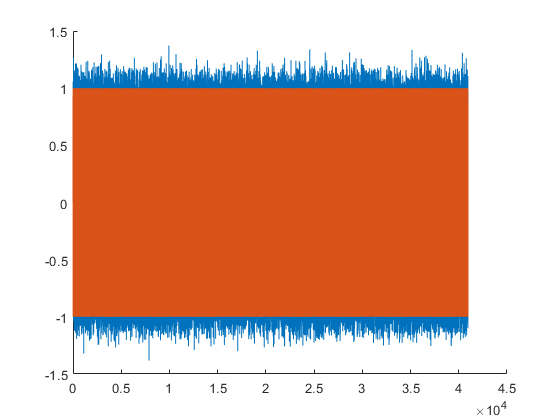

[S,Fs] = audioread('Music library\5 second a new beginning - Copy.mp3');
S = mean(S,2);  

newWave = awgn(S,20,'measured');


len = 5;                                       % Length (sec)
f   = 1E+5;                                     % Frequency (Hz)
Fs  = 8192;                                     % Sampling Frequency (Hz)
t   = linspace(0, len, Fs*len);                 % Time Vector

signal = sin(2*pi*f*t);                         % Signal (10 kHz sine)

% sound(signal, Fs)                               % Original Signal

noise = signal + 0.1*randn(size(signal));
% pause(len+0.5)                                       % Wait For First Sound To Finish Playing
% sound(noise, Fs)                                % Noisy Signal

hold on
% plot(abs(fft(signal)))
% plot(abs(fft(noise)))
plot(noise)
plot(signal)




% len = 5;                                       % Length (sec)
% fff   = 1E+4;                                     % Frequency (Hz)
%                                 % Sampling Frequency (Hz)
% t   = linspace(0, len, Fs*len);                 % Time Vector
% signal = sin(2*pi*fff*t);                         % Signal (10 kHz sine)
%                          % Original Signal
% noise = S + 0.1*randn(size(signal));
% 
% 
% plot(noise)
% plotfft(noise)





% Remove white noise
% Design a lowpass filter with passband frequency of 1 kHz, and stopband
% frequency of 1.4 kHz. Choose a minimum order design.
Fp = 1e3;    % Passband frequency in Hz
Fst = 1.4e3; % Stopband frequency in Hz
Ap = 1;      % Passband ripple in dB
Ast = 95;    % Stopband attenuation in dB


% Design the filter 
df = designfilt('lowpassfir','PassbandFrequency',Fp,...
                'StopbandFrequency',Fst,'PassbandRipple',Ap,...
                'StopbandAttenuation',Ast,'SampleRate',Fs);
            
            
 % Filter the data and compensate for delay
D = mean(grpdelay(df)); % filter delay
ylp = filter(df,[newWave; zeros(D,1)]);
ylp = ylp(D+1:end);           





% hplayer = audioplayer(ylp, Fs);
% play(hplayer);





fart1 = fft(S);
fart2 = fft(newWave);

% hold on
% plot(newWave)
% plot(S)
% hold off


% plot(abs(fart2))
% plot(abs(fart1))









































